load ('NeurotechsmilefrownangryblinkS1filt0p5notch56t64epochs.mat')
originalEEG = EEG

originalEEG = struct with fields:
             setname: 'smilefrownblinksam filt epochs'
            filename: ''
            filepath: ''
             subject: ''
               group: ''
           condition: ''
             session: []
            comments: [2×39 char]
              nbchan: 2
              trials: 409
                pnts: 1000
               srate: 250
                xmin: -0.5000
                xmax: 3.4960
               times: [1×1000 double]
                data: [2×1000×409 single]
              icaact: []
             icawinv: []
           icasphere: []
          icaweights: []
         icachansind: []
            chanlocs: [1×2 struct]
          urchanlocs: []
            chaninfo: [1×1 struct]
                 ref: 'common'
               event: [1×1746 struct]
             urevent: []
    eventdescription: {''  ''  ''  ''}
               epoch: [1×409 struct]
    epochdescription: {}
              reject: [1×1 struct]
               stats: [1×1 struct]



smileCat = (EEG.epochlabelscat=="S pressed");
sum(smileCat)

ans = 151

angryCat = (EEG.epochlabelscat=="A pressed");
sum(angryCat)

ans = 57



if sum(smileCat)>sum(angryCat)
    num_trials_per_cond = sum(angryCat)
else
    num_trials_per_cond = sum(smileCat)
end

num_trials_per_cond = 57

num_trials_per_cond

num_trials_per_cond = 57


idx_trialstokeep = [find(EEG.epochlabelscat=="S pressed",num_trials_per_cond) find(EEG.epochlabelscat=="A pressed",num_trials_per_cond)]

idx_trialstokeep =      7    10    11    13    14    17    18    20    21    22    23    24    32    33    34    35    40    41    43    44    49    50    51    52    58    59    60    72    73    74    75    76    77    78    79    80    81    82    91    93    95    97    99   101   103   104   105   106   107   108


idx_trialstokeep = sort(idx_trialstokeep);

EEG.data = originalEEG.data(:,:,idx_trialstokeep); %Trim the data
EEG.epochlabelscat = originalEEG.epochlabelscat(idx_trialstokeep); %Trim the list of labels
EEG.epochlabelscat = removecats(originalEEG.epochlabelscat(idx_trialstokeep)); %Remove extra categories
EEG.trials = sum(idx_trialstokeep);

for channel = 1:size(EEG.data,1)  
    %Trial by trial baseline removal
    EEG.data(channel,:, :) = EEG.data(channel,:, :) - mean(EEG.data(channel,:, :),2);
end

rng(101); % Do this to theoretically get the same split each time (not important for this situation, but important in my lab.)

% Hold out 20% of the data for the testing set.
ttpart = cvpartition(EEG.epochlabelscat,'HoldOut',.20);

% Set up table of data that includes the trial labels
traindata = table(EEG.epochlabelscat(ttpart.training)','VariableNames',{'labels'});

testdata = table(EEG.epochlabelscat(ttpart.test)','VariableNames',{'labels'});


includedchannels = [1 2]; %channels to included, this will calculate features for each separately 
timewindowforfeatures = [0 2000]; %start and stop in ms. If timepoints don't line up, this will select a slightly later time
timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

tempdata = traindata;
idxt = ttpart.training;

for ch = includedchannels
    clear mydata;
        mydata = squeeze(EEG.data(ch,timewindowepochidx,idxt));
end

[dataPoints, trialNum] = size(mydata)

dataPoints = 501

trialNum = 92

yk = zeros(dataPoints, trialNum);
trialMean = mean(mydata)

trialMean = 1×92 single row vector
    9.2102   -3.8001 -235.9464    8.2188 -104.0533   -2.4648    4.9798   28.4045   59.9688 -136.6710  -32.9192   -1.7878    6.4649   22.0821   -8.7055   -5.9050  -13.3713  -45.3971   -7.3019  -11.1326   -3.2275    2.9628    2.9162   -1.4094   -3.1361    0.8265    1.8149   30.2001  -98.2558   61.7417  -28.0090  141.8293 -236.7631   29.7540  -24.7806   18.6086  -20.0530    1.3306   -9.1199  -25.0543   17.0774   -6.2255  -18.2762    4.6821  -16.9176    0.1218   29.9726  -75.0659  -16.1305  -71.0080


yk = (cumsum((mydata)-mean(mydata)));

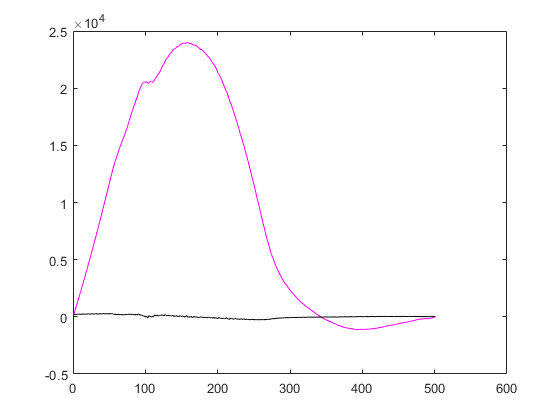

figure
plot(yk(:,78), 'm')
hold on
plot(mydata(:,78), 'k')
hold off

trialMean(78)

ans = single
16.1297

w.totaltimewindow = [1 dataPoints]; %start and stop data points, the size of each trial. If points don't line up, this will select a slightly later time
%timetimewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));

w.timewindowbinsize = [4 5 10 20 25 50]; %This is where you enter the different bin sizes that will be looped through. They should ideally divide into an equal number of data points
w.timewindowoverlap = 0; %128 for another paper

% includedchannels = 1:2;
% for ch = includedchannels    
%     for  tw = 1:size(w.alltimewindowsforfeatures,2)
%                     timewindowforfeatures = w.alltimewindowsforfeatures(:,tw);
%                     timewindowepochidx = (find(EEG.times>=timewindowforfeatures(1),1)):(find(EEG.times>=timewindowforfeatures(2),1));
%                     epochData = squeeze(EEG.data(ch,:,idxt)),2;
%     end
% end

for bin = 1:(size(w.timewindowbinsize,2))
    
    w.starttimes = w.totaltimewindow(1):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    w.endtimes = (w.totaltimewindow(1)-1+w.timewindowbinsize(bin)):(w.timewindowbinsize(bin)-w.timewindowoverlap):w.totaltimewindow(2);
    if w.totaltimewindow(2) - w.starttimes(end) <= w.timewindowoverlap %if increment is smaller than the overlap window
        w.starttimes(end) = []; %then remove the last one (avoids indexing problem, plus you've already used this data)
    end
    if length(w.starttimes) > length(w.endtimes)
        w.endtimes = [w.endtimes w.totaltimewindow(2)];
        warning('The timewindowbinsize does not split evenly into the totaltimewindow, last window will be smaller')
        w.endtimes - w.starttimes
    end
    w.alltimewindowsforfeatures = [w.starttimes; w.endtimes];%(:,1) for first pair
    
    xval = [1:w.timewindowbinsize(bin)]
    
    for trial = 1:trialNum
        
            for L = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
                 databin = yk((w.starttimes(L):w.endtimes(L)), trialNum);
                 if L == 1
                    epochData = databin;
                 else
                    epochData = cat(2, epochData, databin); 
                 end
                
                epochData = [epochData databin];
            end
            
        if trial == 1
            epochTrial = epochData;
        else
            epochTrial = cat(3, epochTrial, epochData); 
        end
        
        for loop = 1:(w.totaltimewindow(2)/w.timewindowbinsize(bin))
            coeff(loop,:,trial) = polyfit(xval,epochTrial(1:(w.timewindowbinsize(bin)),loop,trial), 2);
            
            singleYn = polyval(coeff(loop,:,trial), xval);
            if loop == 1
                binYn = singleYn;
            else
                binYn = cat(2, binYn, singleYn); 
            end
        end
        
        if trial == 1
                yn = binYn;
            else
                yn = cat(3, yn, binYn); 
        end
    end
    
    squeeze(yn)
    yk = yk(1:(size(yn,2)),:) % When testing, yk ended up one row smaller than yn, so this makes yk and yn the same dimensions
    singleFn  = sqrt((sum((yk - squeeze(yn)).^2)/(size(yk,1))));
    if bin == 1
                fn = singleFn;
            else
                fn = cat(3, fn, singleFn); 
    end
end

xval =      1     2     3     4


ans = 500×92 single matrix
	1.0e+03 *

   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340   -0.0340
   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701   -0.0701

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

xval =      1     2     3     4     5


ans = 500×92 single matrix
	1.0e+03 *

   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338   -0.0338
   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705   -0.0705

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

xval =      1     2     3     4     5     6     7     8     9    10


ans = 500×92 single matrix
	1.0e+03 *

   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400   -0.0400
   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693   -0.0693

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

xval =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


ans = 500×92 single matrix
	1.0e+03 *

   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366   -0.0366
   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683   -0.0683

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

xval =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


ans = 500×92 single matrix
	1.0e+03 *

   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306   -0.0306
   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646   -0.0646

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

xval =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


ans = 500×92 single matrix
	1.0e+03 *

   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246   -0.0246
   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605   -0.0605

yk = 500×92 single matrix
	1.0e+05 *

   -0.0001   -0.0003    0.0022   -0.0010    0.0006   -0.0003   -0.0001   -0.0004   -0.0005    0.0013    0.0009   -0.0002   -0.0004    0.0003   -0.0000   -0.0007    0.0003    0.0005    0.0004   -0.0000   -0.0004    0.0000   -0.0001   -0.0002   -0.0001   -0.0004   -0.0003   -0.0001    0.0010   -0.0036    0.0006   -0.0003    0.0023   -0.0017    0.0010   -0.0017    0.0001    0.0009   -0.0001    0.0002   -0.0009   -0.0001    0.0000   -0.0005   -0.0000   -0.0001   -0.0009    0.0021    0.0017    0.0028
   -0.0002   -0.0006    0.0044   -0.0021    0.0012   -0.0006   -0.0002   -0.0009   -0.0010    0.0026    0.0016   -0.0006   -0.0008    0.0004    0.0000   -0.0014    0.0004    0.0009    0.0007   -0.0001   -0.0007   -0.0000   -0.0003   -0.0003   -0.0003   -0.0007   -0.0007   -0.0000    0.0020   -0.0073    0.0012   -0.0006    0.0046   -0.0034    0.0022   -0.0034    0.0003    0.0018   -0.0002    0.0003   -0.0018   -0.0001    0.0000   -0.0009   -0.0000   -0.0003 

flucProfiles = squeeze(fn)

flucProfiles = 92×6 single matrix
	1.0e+04 *

    0.5084    0.5084    0.5084    0.5085    0.5084    0.5083
    0.2839    0.2839    0.2840    0.2842    0.2843    0.2853
    4.5918    4.5918    4.5917    4.5916    4.5914    4.5902
    0.5031    0.5032    0.5032    0.5035    0.5037    0.5053
    1.9691    1.9691    1.9690    1.9689    1.9688    1.9678
    0.3651    0.3651    0.3651    0.3652    0.3651    0.3657
    0.6401    0.6401    0.6401    0.6400    0.6400    0.6395
    0.5958    0.5958    0.5959    0.5963    0.5965    0.5989
    0.3694    0.3694    0.3694    0.3696    0.3697    0.3706
    2.5418    2.5418    2.5417    2.5416    2.5414    2.5403


logFn = log10(flucProfiles)

logFn = 92×6 single matrix
    3.7062    3.7062    3.7062    3.7063    3.7062    3.7062
    3.4532    3.4532    3.4533    3.4537    3.4538    3.4554
    4.6620    4.6620    4.6620    4.6620    4.6619    4.6618
    3.7017    3.7017    3.7018    3.7020    3.7022    3.7035
    4.2943    4.2943    4.2943    4.2942    4.2942    4.2940
    3.5624    3.5624    3.5624    3.5626    3.5624    3.5632
    3.8062    3.8062    3.8062    3.8062    3.8062    3.8059
    3.7751    3.7751    3.7752    3.7755    3.7756    3.7774
    3.5674    3.5675    3.5675    3.5677    3.5678    3.5689
    4.4051    4.4051    4.4051    4.4051    4.4051    4.4049


logBinSize = log10(w.timewindowbinsize)

logBinSize =     0.6021    0.6990    1.0000    1.3010    1.3979    1.6990


figure
plot(logBinSize, logFn(92,:), 'O')
p = polyfit(logBinSize,logFn(92,:),1)

p = 1×2 single row vector
    0.0065    3.2668


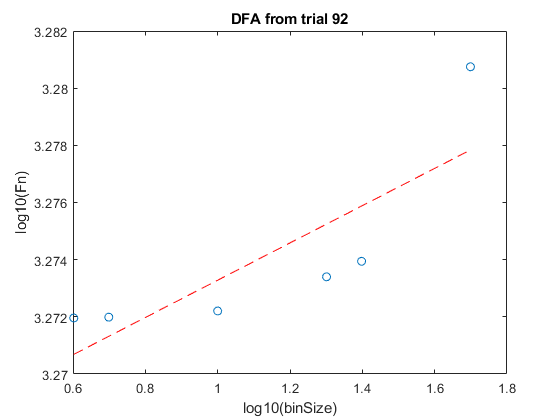

f = polyval(p,logBinSize);
hold on
plot(logBinSize,f,'--r')
title('DFA from trial 92')
xlabel('log10(binSize)')
ylabel('log10(Fn)')
hold off

DFA = (mean((logFn./logBinSize)'))'

DFA = 92×1 single column vector
    3.8077
    3.5481
    4.7895
    3.8033
    4.4117
    3.6600
    3.9103
    3.8788
    3.6653
    4.5257


eegMFL = (log10(sqrt(sum((diff(mydata)).^2))))'

eegMFL = 92×1 single column vector
    2.4392
    2.5105
    2.5965
    2.6629
    2.6000
    2.6133
    2.3619
    2.0238
    2.8492
    2.7797


features = [table(DFA, eegMFL), traindata]

features = 92×3 table
     DFA      eegMFL     labels  
    ______    ______    _________

    3.8077    2.4392    S pressed
    3.5481    2.5105    S pressed
    4.7895    2.5965    S pressed
    3.8033    2.6629    S pressed
    4.4117       2.6    S pressed
      3.66    2.6133    S pressed
    3.9103    2.3619    S pressed
    3.8788    2.0238    S pressed
    3.6653    2.8492    S pressed
    4.5257    2.7797    S pressed
    3.9874    2.6154    S pressed
    3.5014    2.6078    S pressed
    3.7328    2.6171    S pressed
    3.3072    2.6619    S pressed
    3.4636    2.8164    S pressed
    3.6324    2.8892    S pressed


polyfit(xval,epochTrial(1:(w.timewindowbinsize(bin)),loop,trial), 2)

ans = 1×3 single row vector
	1.0e+03 *

   -0.0003    0.0120   -4.4492
